# Wave Parameter Extraction Pipeline

This MATLAB LiveScript serves as a live document to show the implementation of the SAR wave parameter extraction pipeline with additional documentation. Documentation notes are included before code blocks which explain the code which follows.

## Prerequisites

### Software Prerequisites

#### SNAP ESA

SNAP is a tool developed by the European Space Agency (ESA) to process SAR data obtained from Sentinel Satellites. SNAP is used to pre-process data in this pipeline and is essential to install.

To install SNAP please do the following:

- Download SNAP [here](https://step.esa.int/main/download/snap-download/) for your OS distribution

- Choose only the Sentinel Toolboxes installer

- Install SNAP and follow the onscreen instructions. It is only necessary to install the Sentinel-1 Toolbox

### MATLAB Prerequisites

Python 3.8 (Need to check version in MATLAB)

pe = pyenv;
pyVersion = pe.Version;
if ~(strcmp(pyVersion, "3.8"))
    pe(Version="3.8")
end

CDS Toolbox

#### M_Map

M_Map is a mapping package for MATLAB which allows data plots on different world maps.

To use M_Map please do the following:

- Download the zipped package [here](https://www.eoas.ubc.ca/~rich/map.html#download) and

- Add the extracted folder to your MATLAB path

*Note:* A copy of the M_Map package is included on this git repo in the following path: 

#### wgrid

## Obtain SAR Data

Copernicus SciHub closed October 2023 - update 

SAR data from Sentinel-1A can be downloaded from [Copernicus SciHub](https://scihub.copernicus.eu/dhus/#/home). In order to download data, you need to register an account on the site.

Once you have registered your account, you can search for SAR data on the site by choosing the appropriate filters and region. The region you search is set by right-clicking and drawing a rectangle, otherwise you can left-click and draw the vertices of any polygon. Recomended filters are:

- **Sensing Period: **As desired

- **Satellite Platform:** S1A

- **Product Type:** GRD

- **Polarisation:** As desired

After searching with your filters, you will see all the available data within this region. Clicking on a red footprint on the map, shows a preview of these data, and the data can be downloaded from the pop-up. 

*Note: *These data are in excess of 1GB, so large amounts of storage space is required. Use an external hard drive if possible.

## **Pre-Process SAR Data**

After downloading SAR data from [Copernicus SciHub](https://scihub.copernicus.eu/dhus/#/home), open SNAP and import the data. These data can be viewed as follows:

- Click the '+' next to the dataset

- Click the '+' next to the *Bands* folder

- Open the desired band to preview the image

### Thermal Noise Calibration

**This needs to be done first**

To remove thermal noise, click *Radar -> Radiometric -> S1 Thermal Noise Removal. *This will bring up a window where the following needs to be done.

- Ensure the file will save as *BEAM-DIMAP*

- Check that *Remove Thermal Noise* is checked in the *Processing Parameters* window

- Select a specific polarisation (If desired)

- Rename the output file (*Target Product) *if desired

- Check the *Open in SNAP* checkbox

After clicking *Run,* SNAP will begin removing thermal noise from the selected data and once complete will open in the *Product Explorer *sidebar.

### Radiometric Calibration

To radiometrically calibrate the SAR data, ensure that the **noise calibrated product is selected**, then click *Radar -> Radiometric -> Calibrate *This will bring up a window where the following needs to be done.

- Ensure the file will save as *BEAM-DIMAP*

- Check that **only** *Output sigma0 band* is checked in the *Processing Parameters* window

- Select a specific polarisation (If desired)

- Rename the output file (*Target Product) *if desired

- Check the *Open in SNAP* checkbox

After clicking *Run,* SNAP will begin radiometric calibration from the selected data and once complete will open in the *Product Explorer *sidebar.

### Export Incidence Angle

In order to access the incidence angle of each pixel in the the SAR data, the following process needs to be followed.

- Click the '+' next to the *Tie-Point Grids* folder

- Right-click on the *incident_angle* band

- Select *Band Maths*

- Rename the band to "Incidence_Angle" and click OK

### Exporting as NetCDF

In order to export these pre-processed SAR data in a format supported by MATLAB, the following process needs to be followed.

- Click *File*

- Hover over the *Export* option, and select **NetCDF4-BEAM**

- If your file explorer is opened, click on *Subset... *on the right hand side of the dialog box

- This will bring up a new window with four different menus.

- You can take a Spatial Subset of the image using either pixel or geographical coordinates in the *Spatial Subset *menu

- Ensure that under the *Band Subset* menu, your desired bands are selected, as well as your created ***Incidence_Angle***** band. **

- Ensure that under the *Metadata Subset* menu, all options are selected

- After checking all of these parameters, click OK, and name the file as desired and save it in your desired location

## Take transects and subdivide

After exporting the SAR data as a NetCDF file, use the following commands to import the data and metadata into MATLAB.

filepath = "D:\caseStudy_tnr_Cal_all_locs_1.nc";
% Import data values
ncImport = ncinfo(filepath);
% Update the band to import as required
sarData = ncread(filepath,'Sigma0_VV')';
metadata = ncinfo(filepath,'metadata');
incidenceAngleFull = ncread(filepath,'Incidence_Angle')';
latGrid = ncread(filepath,'Lat')';
lonGrid = ncread(filepath,'Lon')';

## View SAR Data

The shown pixel grid is useful to decide on where to begin transects.

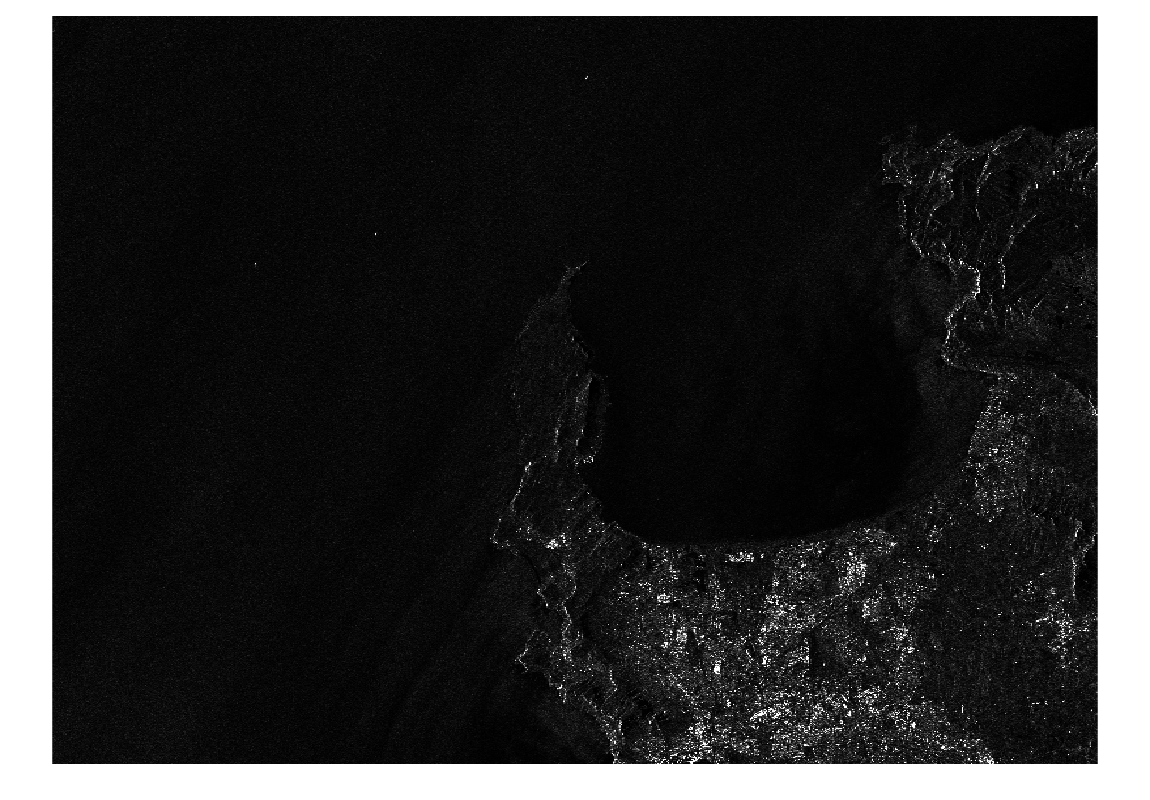

figure(1);
imshow(sarData);

### Define Transect Parameters

Enter the number of desired transects to take, the start point (in pixels), along with the angle at which to take the transects. The angle is calculated from the positive x-axis clockwise.

topLeftLat = -34;
topLeftLon = 18.25;
[topLeftx, topLefty] = latToPixel(latGrid,lonGrid,topLeftLat,topLeftLon);
numTransects = 1;
th = 30;
[transectData, transectPositions] = get512Transects(sarData,0,topLefty,th,numTransects);

0 input top left x value changed to 1


[incidenceAngle, incidencePositions] = get512Transects(incidenceAngleFull,1,1,th,numTransects);

% Results plotting
[transectData1,transect1Positions] = get512Transects(sarData,3833,2995,0,1);
[transectData2,transect2Positions] = get512Transects(sarData,6455,3761,0,1);
[transectData3,transect3Positions] = get512Transects(sarData,2537,7411,0,1);
[transectData4,transect4Positions] = get512Transects(sarData,1,6637,0,1);
[incidenceAngle1, incidencePositions1] = get512Transects(incidenceAngleFull,3833,2995,0,1);
[incidenceAngle2, incidencePositions2] = get512Transects(incidenceAngleFull,6455,3761,0,1);
[incidenceAngle3, incidencePositions3] = get512Transects(incidenceAngleFull,2537,7411,0,1);
[incidenceAngle4, incidencePositions4] = get512Transects(incidenceAngleFull,1,6637,0,1);

The original data, with shown transects can be plotted.

Generating plot...


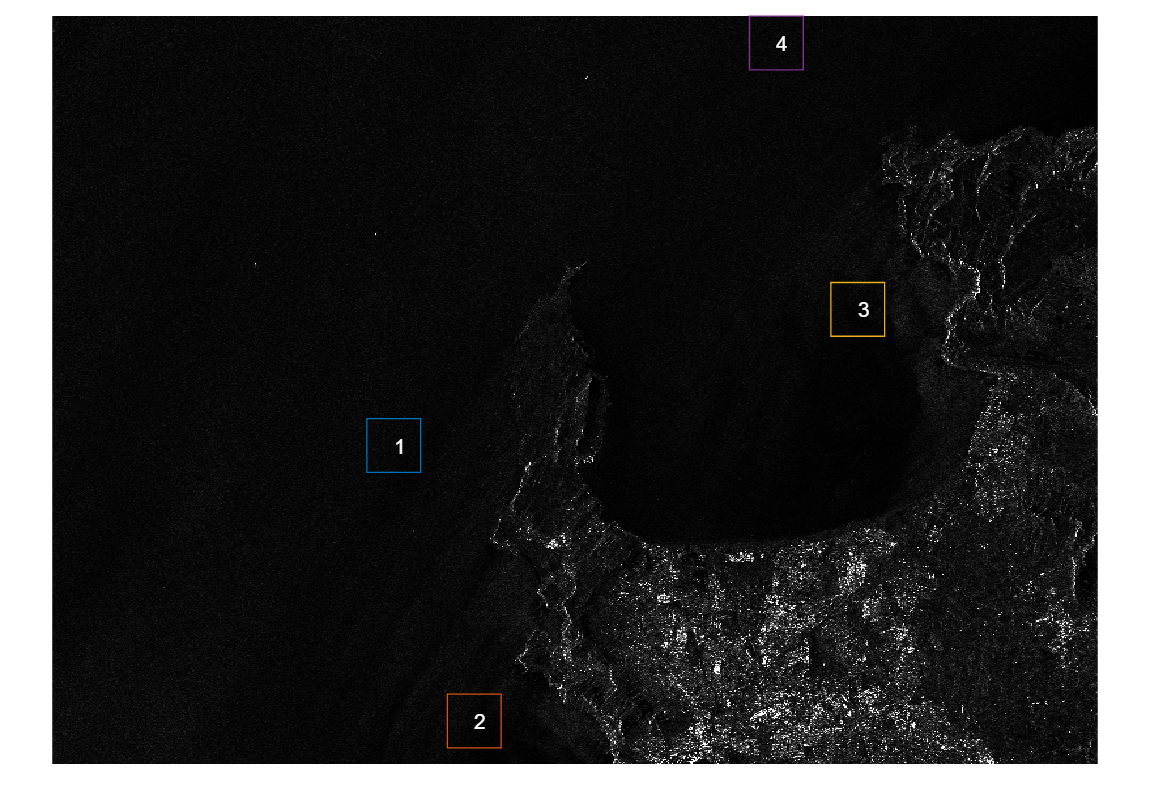

plotFullScene = true;
if plotFullScene
    disp('Generating plot...');    
    figure;
    imshow(sarData)
    hold on;
    % Results plotting
    annotate512Transect(2995,3833,1,'#0072bd','white',0);
    annotate512Transect(3761,6455,2,'#d95319','white',0);
    annotate512Transect(7411,2537,3,'#edb120','white',0);
    annotate512Transect(6637,1,4,'#7e2f8e','white',0);
    % for i = 1:numTransects
    %     annotate512Transect(transectPositions(i,2),transectPositions(i,1),i,'red','white',0);
    % end
    % 
    % title('Sentinel-1A data with transects displayed')
    hold off
end

disp('Done');

Done


Choose which transects to plot. Enter the values as a comma seperated list.

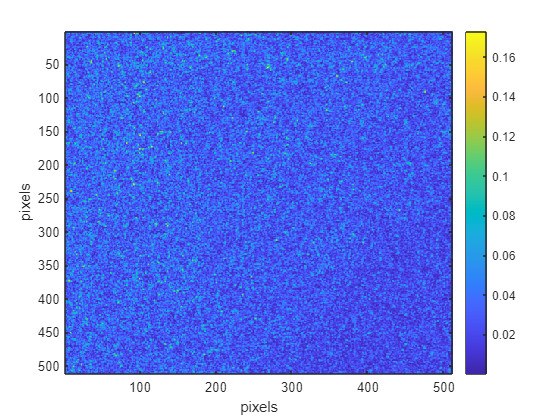

% Results plotting
figure;
imagesc(transectData1);
colorbar;
xlabel('pixels')
ylabel('pixels')

transectsToPlot = "1";
strTransects = strsplit(transectsToPlot,',');
transectsToPlot = str2double(strTransects);
% Check if any element in the vector is greater than n
if any(transectsToPlot > numTransects)
    error('At least one number given is greater than the number of transects, %.0f.\n', numTransects);
end

rowsToPlot = ceil(length(transectsToPlot)/2);

figure;
disp('Generating plot...');

Generating plot...


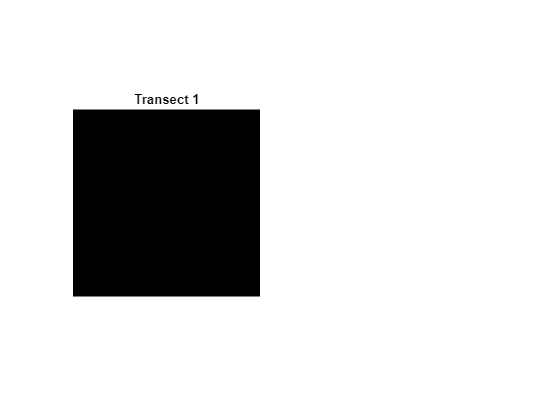

for i = 1:length(transectsToPlot)
    subplot(rowsToPlot,2,i);
    transectNum = transectsToPlot(i);
    imshow(transectData(:,:,transectNum));
    title(['Transect ', num2str(transectNum)])
end

disp('Done');

Done


## Generate Wave Spectra

### Download Associated Wave Data

func = helperFunctions;

captureDate = func.getCaptureDate(metadata);
[noaaDateStr, noaaHourStr] = func.getNOAAParams(captureDate);
noaaUrl = func.getNOAAUrl(noaaDateStr, noaaHourStr);

Set the name for the saved downloaded `.grib2` file.

waveDownloadName = "wave_data";
% Check file ends in .grib2

waveDataExtension = '.grib2';

if ~endsWith(waveDownloadName, waveDataExtension)
    waveDownloadName = strcat(waveDownloadName,waveDataExtension);
end
waveFilePath = downloadNOAAWaveFile(noaaUrl,waveDownloadName);

Set the location of wgib and the downloaded `.grib2` filepath. Choose if you'd like to plot your downloaded data along with the type to plot.

GribPath = "C:\Users\ryanj\Downloads\20_Oct_Wave_data.grib2";
wgrib2Path = "C:\Users\ryanj\Downloads\wgrib2.exe";
[GribPath,~,~] = fileparts(GribPath);
GribPath = strcat(GribPath,'\');
[wgrib2Path,~,~] = fileparts(wgrib2Path);
waveStruct = getGribStruct(wgrib2Path,GribPath);

Generating plot...


ans =   476×1 graphics array:

  Patch                  (m_coast_land)
  GraphicsPlaceholder
  Patch                  (m_coast_land)
  Patch                  (m_coast_land)
  GraphicsPlaceholder
  Patch                  (m_coast_land)
  GraphicsPlaceholder
  GraphicsPlaceholder
  GraphicsPlaceholder
  GraphicsPlaceholder
  GraphicsPlaceholder
  GraphicsPlaceholder
  GraphicsPlaceholder
  Patch                  (m_coast_land)
  GraphicsPlaceholder
  GraphicsPlaceholder
  GraphicsPlaceholder
  GraphicsPlaceholder
  Patch                  (m_coast_land)
  GraphicsPlaceholder
  GraphicsPlaceholder
  GraphicsPlaceholder
  GraphicsPlaceholder
  GraphicsPlaceholder
  Patch                  (m_coast_land)
  GraphicsPlaceholder
  GraphicsPlaceholder
  GraphicsPlaceholder
  GraphicsPlaceholder
  GraphicsPlaceholder
  GraphicsPlaceholder
  GraphicsPlaceholder
  GraphicsPlaceholder

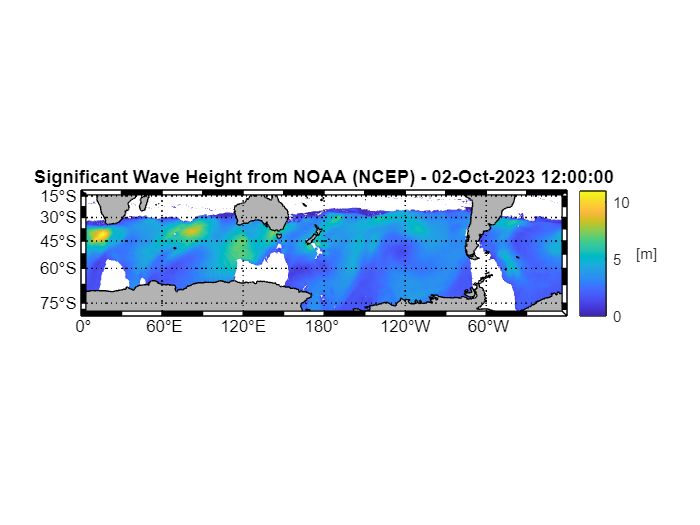

Done


noaaPlot = true;
noaaValToPlot = 'significantWaveHeight';
if noaaPlot
    disp('Generating plot...');
    noaaDataPlot('miller',waveStruct,noaaValToPlot);
    disp('Done');
end

Set the location at which to generate wave spectra for as well as the data resolution.

latitude = -34.204;
longitude = 18.28666944;
resolution = 0.25;
[gridLat, gridLon] = createLatLonGrid(latitude, longitude, resolution);
startLat = max(gridLat);
startLon = min(gridLon);
endLat = min(gridLat);
endLon = max(gridLon);
waveVals = getSubsetWaveVals(waveStruct,startLat,startLon,endLat,endLon);

% Results plotting
waveStruct = waveStruct(2);
waveVals1 = getSubsetWaveVals(waveStruct,-34.25,18.25,-34.25,18.25);
waveVals2 = getSubsetWaveVals(waveStruct,-34.5,18.25,-34.5,18.25);
waveVals3 = getSubsetWaveVals(waveStruct,-34.25,18.75,-34.25,18.75);
waveVals4 = getSubsetWaveVals(waveStruct,-34.5,18.75,-34.5,18.75);

### Generate One-dimensional Wave Spectra

Define and instantiate variables for the one-dimensional wave spectra

%imageSize = size(transectData,1);
imageSize = 512;
w = linspace(0,2*pi,imageSize)';
f = linspace(0,1,imageSize)';
Hs = waveVals.significantWaveHeight(2,2);
T0 = waveVals.significantWavePeriod(2,2);
w0 = 2*pi./T0;
f0 = 1./T0;
gammaVal = 1.3713;
multipleWaveSpectra = false;
if multipleWaveSpectra
    S = generateMultipleJONSWAP(waveVals,gammaVal,w,1);   
else
    S = generateSingleJONSWAP(Hs,w0,gammaVal,w);
end

plot1DWaveSpectra = true;
displaywPeak = false;
plotLats = false;
plotLons = false;
if plot1DWaveSpectra
    disp('Generating plot...');
    waveSpectrumPlot(waveVals,S,w,multipleWaveSpectra,displaywPeak,plotLats,plotLons);
    disp('Done');
end    

Generating plot...


Done


% Results plotting
imageSize = 512;
w = linspace(0,2*pi,imageSize)';
f = linspace(0,1,imageSize)';
Hs = waveVals1.significantWaveHeight;
T0 = waveVals1.significantWavePeriod;
w0 = 2*pi./T0;
f0 = 1./T0;
gammaVal = 1.3713;
multipleWaveSpectra = false;
if multipleWaveSpectra
    S = generateMultipleJONSWAP(waveVals,gammaVal,w,1);   
else
    S = generateSingleJONSWAP(Hs,w0,gammaVal,w);
    S = func.resize(S(2:end),w);
end

plot1DWaveSpectra = false;
displaywPeak = false;
plotLats = false;
plotLons = false;
if plot1DWaveSpectra
    disp('Generating plot...');
    waveSpectrumPlot(waveVals1,S,w,multipleWaveSpectra,displaywPeak,plotLats,plotLons);
    %matlab2tikz('../plots/results/oneDWaveSpec1_20Oct.tex');
    disp('Done');
end    

### Generate Two-dimensional Wave Spectra

Generating plot...


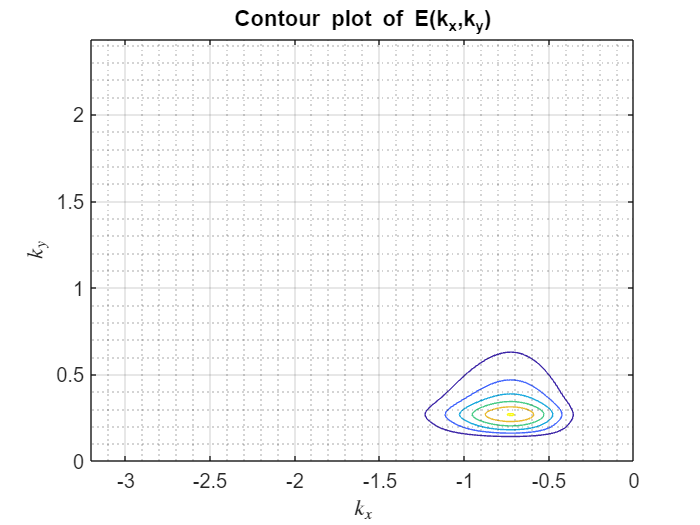

Done


g = 9.81;
[D,theta] = generateDirectionalDistribution(waveVals,w,1);
E = generate2DWaveSpectrum(S,D);
if size(E,3) == 9
    E = E(:,:,5,1);
else
    E = E(:,:,:,1);
end    
d = 70;
%% Calculate E(k_x,k_y)
k = (w.^2./g)';
k_x = k.*cos(waveVals.direction(2,2));
k_y = k.*sin(waveVals.direction(2,2));
[E_k,k] = waveNumberSpectrum(E,w,k,d);
[E_k_inv,k_inv] = waveNumberSpectrum(E,w,fliplr(-k),d);
k_x_inv = k_inv.*cos(waveVals.direction(2,2));
k_y_inv = k_inv.*sin(waveVals.direction(2,2));
plot2DWaveSpectra = true;
wOrK = 1;
contourOrSurf =1;
if plot2DWaveSpectra
    if wOrK
        disp('Generating plot...');
        twoDWaveSpectrumPlot(E_k,wOrK,contourOrSurf,w,theta,k_x,k_y); 
        %matlab2tikz(['../plots/Valcontour_E_k.tex'])
        disp('Done');
    else
        disp('Generating plot...');
        twoDWaveSpectrumPlot(E,wOrK,contourOrSurf,w,theta,k_x,k_y); 
        disp('Done');
    end    
end

% Results plotting
g = 9.81;
waveVals = waveVals1;
[D,theta] = generateDirectionalDistribution(waveVals,w,1);
E = generate2DWaveSpectrum(S,D);
if size(E,3) == 9
    E = E(:,:,5,1);
else
    E = E(:,:,:,1);
end    
d = 130;
%% Calculate E(k_x,k_y)
k = (w.^2./g)';
k_x = k.*cos(waveVals.direction);
k_y = k.*sin(waveVals.direction);
[E_k,k] = waveNumberSpectrum(E,w,k,d);
[E_k_inv,k_inv] = waveNumberSpectrum(E,w,fliplr(-k),d);
k_x_inv = k_inv.*cos(waveVals.direction);
k_y_inv = k_inv.*sin(waveVals.direction);
plot2DWaveSpectra = false;
wOrK = 0;
contourOrSurf =1;
if plot2DWaveSpectra
    if wOrK
        disp('Generating plot...');
        twoDWaveSpectrumPlot(E_k,wOrK,contourOrSurf,w,theta,k_x,k_y); 
        matlab2tikz(['../plots/results/contour_E_k4_20Oct.tex'])
        disp('Done');
    else
        disp('Generating plot...');
        twoDWaveSpectrumPlot(E,wOrK,contourOrSurf,w,theta,k_x,k_y); 
        matlab2tikz('../plots/results/contour_E_w4_20Oct.tex');
        disp('Done');
    end    
end

## SAR Spectrum Calculation

#### Generate observed SAR Spectra [TODO]

The SAR Spectrum of each transect can be plotted as well as the full scene spectrum after taking a 2D FFT of `transectData`. The same transects are used as defined in the previous section.

% Spectral bandwidth calculation
func = helperFunctions;
if multipleWaveSpectra
    S_1 = S(:,:,5);
else
    S_1 = S;
end
S_1 = S_1(2:end);

Unable to resolve the name 'func.resize'.

S_1 = func.resize(S_1(2:end),w);
for i=2:length(w)
    dw(i) = w(i)-w(i-1);
end
dw = mean(dw);
S_norm = S_1 / (trapz(S_1).*dw);
spectralMean = trapz(w.*S_norm).*dw;
spectralVar = trapz((w-spectralMean).^2.*S_norm).*dw;
spectralBW = sqrt(spectralVar);
plotTransectSARSpectrum = true;
transectsToPlot = "1";
strTransects = strsplit(transectsToPlot,',');
transectsToPlot = str2double(strTransects);
% Check if any element in the vector is greater than n
if any(transectsToPlot > numTransects)
    error('At least one number given is greater than the number of transects, %.0f.\n', numTransects);
end

spectrumThreshold =35; 
%57 has been good previously
if plotTransectSARSpectrum
    disp('Generating plot...');
    for i = 1:length(transectsToPlot)
        transectNum = transectsToPlot(i);
        intensityFFT = abs(fftshift(fft2(transectData(:,:,transectNum))));
        SARSpectrumPlot(intensityFFT,spectrumThreshold,spectralBW,1);
        title(['Transect ', num2str(transectNum),' observed SAR Spectrum'])
        %matlab2tikz(['../plots/results/observedSARSpectrum_',num2str(i),'.tex'])
    end
    disp('Done');
end    

Generating plot...


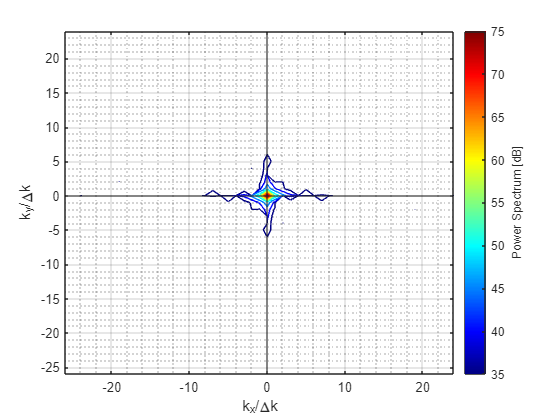

Done


% Results plotting
% Spectral bandwidth calculation
func = helperFunctions;
if multipleWaveSpectra
    S_1 = S(:,:,5);
else
    S_1 = S;
end
S_1 = S_1(2:end);
S_1 = func.resize(S_1(2:end),w);
for i=2:length(w)
    dw(i) = w(i)-w(i-1);
end
dw = mean(dw);
S_norm = S_1 / (trapz(S_1).*dw);
spectralMean = trapz(w.*S_norm).*dw;
spectralVar = trapz((w-spectralMean).^2.*S_norm).*dw;
spectralBW = sqrt(spectralVar);
plotTransectSARSpectrum = true;
transectsToPlot = "1";
strTransects = strsplit(transectsToPlot,',');
transectsToPlot = str2double(strTransects);
% Check if any element in the vector is greater than n
if any(transectsToPlot > numTransects)
    error('At least one number given is greater than the number of transects, %.0f.\n', numTransects);
end

spectrumThreshold =32; 
%Using 32
if plotTransectSARSpectrum
    disp('Generating plot...');
    for i = 1:length(transectsToPlot)
        transectNum = transectsToPlot(i);
        intensityFFT = abs(fftshift(fft2(transectData1)));
        SARSpectrumPlot(intensityFFT,spectrumThreshold,spectralBW,1);
        %title(['Transect ', num2str(transectNum),' observed SAR Spectrum'])
        %matlab2tikz(['../plots/results/observedSARSpectrum2_20Oct.tex'])
    end
    disp('Done');
end    

## Hasselmann Procedure

nonLinOrder = 1;
incidenceAngle = incidenceAngle(:,:,1);
r = ones(size(incidenceAngle));
intensityFFT = abs(fftshift(fft2(transectData(:,:,1))));
P_s_pipeline = generateSARSpectrumOceanWaves(k,k_y,k_x,E_k,metadata,incidenceAngle,r,nonLinOrder,w);

m = 0, n = 1 
P_(n,2n-2) used
m = 1, n = 1 
P_(n,2n-1) used 
m = 2, n = 1 
P_(n,2n) used 


% Results calculations
nonLinOrder = 1;
incidenceAngle = incidenceAngle1;
r = ones(size(incidenceAngle));
intensityFFT = abs(fftshift(fft2(transectData1)));
P_s_pipeline1 = generateSARSpectrumOceanWaves(k,k_y,k_x,E_k,metadata,incidenceAngle,r,nonLinOrder,w);

m = 0, n = 1 
P_(n,2n-2) used
m = 1, n = 1 
P_(n,2n-1) used 
m = 2, n = 1 
P_(n,2n) used 


Done


 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 
 *** Found colormap/jet to be a pretty good match for your color map (||diff||=0.00684254).


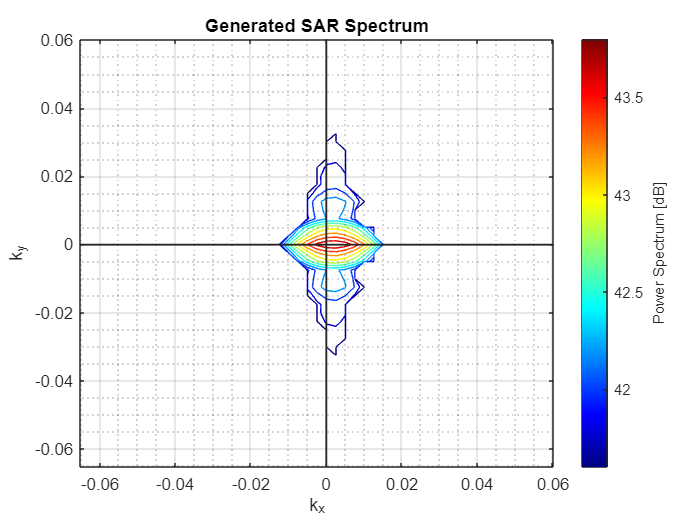

 *** Found colormap/jet to be a pretty good match for your color map (||diff||=0.00684254).
 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


plotGeneratedSARSpectrum = true;
if plotGeneratedSARSpectrum
    spectrumThresholdGen = 120;
    SARSpectrumPlot(20*log10(abs(P_s_pipeline)),spectrumThresholdGen,spectralBW,0);
    title('Generated SAR Spectrum')
    disp('Done');
    %matlab2tikz(['../plots/generatedSARSpectrum_Verify.tex'])
end  

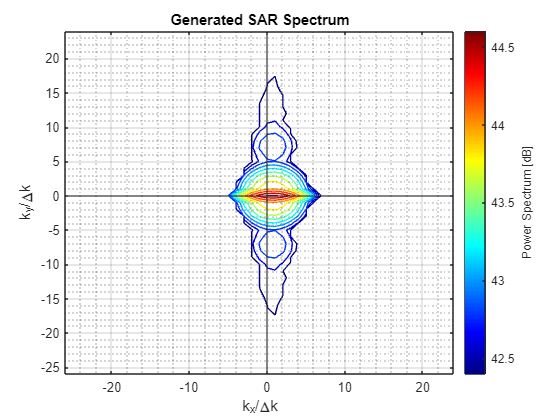

Done


% Results plotting
plotGeneratedSARSpectrum = true;
if plotGeneratedSARSpectrum
    spectrumThresholdGen = 130;
    % 130 used
    SARSpectrumPlot(20*log10(abs(P_s_pipeline1)),spectrumThresholdGen,spectralBW,1);
    title('Generated SAR Spectrum')
    disp('Done');
    %matlab2tikz(['../plots/results/generatedSARSpectrum1_20Oct.tex'])
end    

figure;
contour(20*log10(abs(P_s_pipeline)));
title('Generated SAR Spectrum')

nonLinOrder = 1;
incidenceAngle = incidenceAngle(:,:,1);
r = ones(size(incidenceAngle));
P_s_pipeline = generateSARSpectrumOceanWaves(k,k_y,k_x,E_k,metadata,incidenceAngle,r,nonLinOrder,w);
iterations = 7;
iterationVec = linspace(1,iterations,iterations);
[J,En,Pn,sigWaveHeight,sigWavePeriod] = inversion(iterations,P_s_pipeline,intensityFFT,E_k,E_k_inv,k,k_x,k_y,B,mu,Ts_k,Ts_k_inv,P_s_lin,p_s_coeff,p_s_coeff_inv,dk_x,dk_y,metadata,incidenceAngle,r,w,theta);

% Results calculations
nonLinOrder = 1;
incidenceAngle = incidenceAngle1;
r = ones(size(incidenceAngle));
P_s_lin = imageVarianceSpectrum(k,k_x,k_y,k_inv,k_x_inv,k_y_inv,E_k,E_k_inv,metadata,incidenceAngle);
E_k_inv = func.resize(E_k_inv(:,1:end-7),E_k);
[p_s_coeff,beta,xi_sqr,~] = quasilinearCoeff(k,k_y,k_x,E_k,metadata,incidenceAngle);
p_s_coeff_inv = quasilinearCoeff(k_inv,k_y_inv,k_x_inv,E_k_inv,metadata,incidenceAngle);
mu = calculateWeight(intensityFFT);
B = calculateNormalisationConstant(E_k);

E_k = func.resize(E_k(2:end,2:end),incidenceAngle);
E_k_inv = func.resize(E_k_inv(2:end,2:end),incidenceAngle);

look = func.getLook(metadata);
look = func.look(look);
polarisation = func.getPolarisation(metadata);
%k_y = func.resize(k_y,th(1,:));
k_l = func.kl(look,k_y);
k_l_inv = func.kl(look,k_y_inv);
omega = func.omega(k);
mu_Th = 0.5;
Th_k = func.hydroMTF(omega,mu_Th,k,k_y);
Th_k = func.resize(Th_k(2:end),omega);
Tt_k = func.tiltMTF(polarisation,k_l,incidenceAngle);
TR_k = func.rarMTF(Tt_k,Th_k);

Th_k_inv = func.hydroMTF(omega,mu_Th,k_inv,k_y_inv);
Th_k = func.resize(Th_k_inv(2:end),omega);
Tt_k_inv = func.tiltMTF(polarisation,k_l_inv,incidenceAngle);
TR_k_inv = func.rarMTF(Tt_k_inv,Th_k_inv);
TR_k_inv = func.resize(TR_k_inv(:,1:end-1),E_k);

Tv_k = func.rangeVelocityTF(omega,incidenceAngle,k_l,k);
Tv_k = func.resize(Tv_k(:,2:end),E_k);

Tvb_k = func.velocityBunchingMTF(beta,k_x,Tv_k);
Tvb_k = func.resize(Tvb_k(:,2:end),E_k);

Tv_k_inv = func.rangeVelocityTF(omega,incidenceAngle,k_l,fliplr(-k));
Tv_k_inv = func.resize(Tv_k_inv(:,2:end-3),E_k);

Tvb_k_inv = func.velocityBunchingMTF(beta,k_x_inv,Tv_k_inv);
Tvb_k_inv = func.resize(Tvb_k_inv(:,2:end-5),E_k);

Ts_k_inv = func.sarImagingMTF(TR_k_inv,Tvb_k_inv);
Ts_k = func.sarImagingMTF(TR_k,Tvb_k);

[M, N] = size(intensityFFT);
dx = spectralBW;
dy = spectralBW;
kx = (-M/2:M/2-1) / (M * dx);
ky = (-N/2:N/2-1) / (N * dy);
% Calculate Δk (the spacing between k values)
dk_x = kx(2) - kx(1);
dk_y = ky(2) - ky(1);
iterations = 7;
iterationVec = linspace(1,iterations,iterations);
[J,En,Pn,En_w_th,En_w,sigWaveHeight,sigWavePeriod] = inversion(iterations,P_s_pipeline1,intensityFFT,E_k,E_k_inv,k,k_x,k_y,B,mu,Ts_k,Ts_k_inv,k_x_inv,k_y_inv,P_s_lin,p_s_coeff,p_s_coeff_inv,dk_x,dk_y,metadata,incidenceAngle,r,w,D,theta);

m = 0, n = 1 
P_(n,2n-2) used
m = 1, n = 1 
P_(n,2n-1) used 
m = 2, n = 1 
P_(n,2n) used 
Significant Wave Height = 1.0237 with iterations = 1
Significant Wave Period = 5.3939 with iterations = 1
m = 0, n = 1 
P_(n,2n-2) used
m = 1, n = 1 
P_(n,2n-1) used 
m = 2, n = 1 
P_(n,2n) used 
Significant Wave Height = 1.022 with iterations = 2
Significant Wave Period = 5.4545 with iterations = 2
m = 0, n = 1 
P_(n,2n-2) used
m = 1, n = 1 
P_(n,2n-1) used 
m = 2, n = 1 
P_(n,2n) used 
Significant Wave Height = 1.0053 with iterations = 3
Significant Wave Period = 5.5165 with iterations = 3
m = 0, n = 1 
P_(n,2n-2) used
m = 1, n = 1 
P_(n,2n-1) used 
m = 2, n = 1 
P_(n,2n) used 
Significant Wave Height = 1.1287 with iterations = 4
Significant Wave Period = 5.5165 with iterations = 4
m = 0, n = 1 
P_(n,2n-2) used
m = 1, n = 1 
P_(n,2n-1) used 
m = 2, n = 1 
P_(n,2n) used 
Significant Wave Height = 1.2003 with iterations = 5
Significant Wave Period = 5.5799 with iterations = 5
m = 0, n = 1 
P_(n,2n

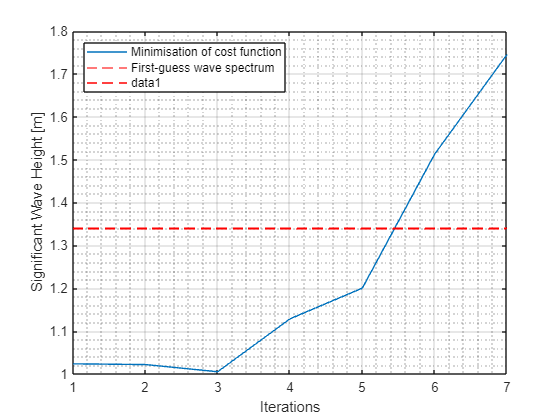

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 


 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


% Plot waveHeight
figure;
plot(iterationVec,sigWaveHeight, 'DisplayName','Minimisation of cost function');
yline(waveVals1.significantWaveHeight,'LineStyle','--','Color',	'r','DisplayName','First-guess wave spectrum');
ylabel('Significant Wave Height [m]')
xlabel('Iterations')
grid on;
grid minor;
legend('show','Location','northwest')
matlab2tikz(['../plots/results/sigWaveHeightMinimisation1_7iterations_20Oct.tex']);

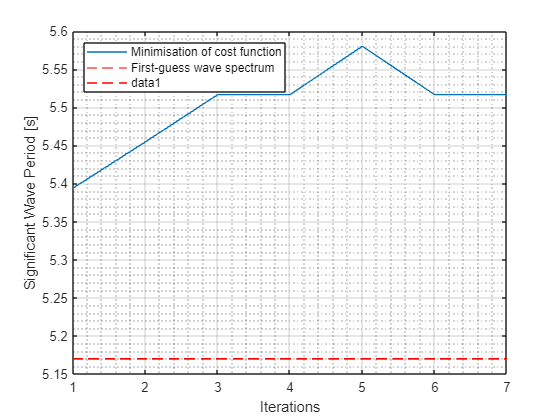

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 


 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


% Plot waveperiod
figure;
plot(iterationVec,sigWavePeriod, 'DisplayName','Minimisation of cost function');
yline(waveVals1.significantWavePeriod,'LineStyle','--','Color',	'r','DisplayName','First-guess wave spectrum');
ylabel('Significant Wave Period [s]')
xlabel('Iterations')
grid on;
grid minor;
legend('show','Location','northwest')
%matlab2tikz(['../plots/results/sigWavePeriodMinimisation1_7iterations_20Oct.tex']);

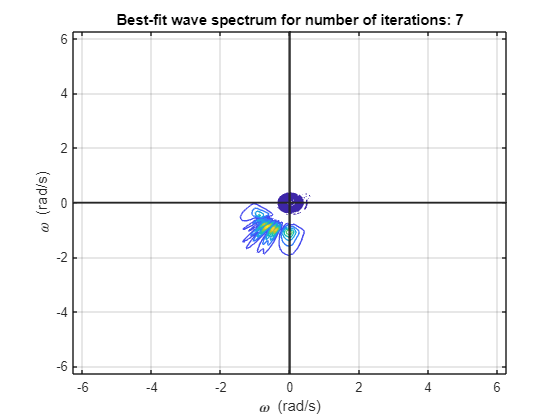

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 


 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


%% Plot output wave spectra

[t,r] = meshgrid(theta,w);
[x,y] = pol2cart(t,r);

figure;
%surf(x,y,En_w_th,'LineStyle','none');
contour(x,y,En_w_th);
title(['Best-fit wave spectrum for number of iterations: ',num2str(iterations)]);
yline(0);
xline(0);
grid on;
xlabel('\omega (rad/s)'), ylabel('\omega (rad/s)');
%matlab2tikz(['../plots/results/contour_E_w1_7iterations_20Oct.tex']);

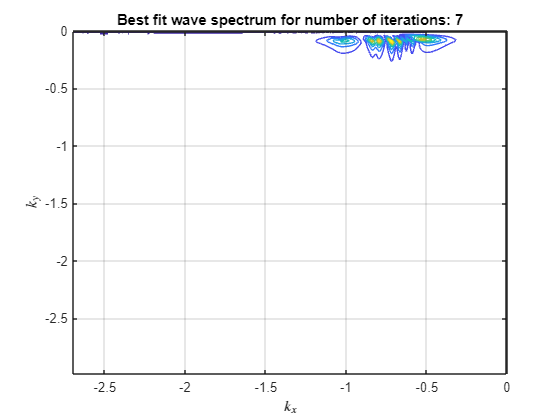

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 


 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


EDiff = abs(En_w_th - E);
figure;
%surf(x,y,EDiff,'LineStyle','none');
contour(x,y,EDiff);
%title(['Number of iterations: ',num2str(iterations)]);
yline(0);
xline(0);
grid on;
xlabel('\omega (rad/s)'), ylabel('\omega (rad/s)');

figure;
%surf(k_x,k_y,En,'LineStyle','none')
contour(k_x,k_y,En);
title(['Best fit wave spectrum for number of iterations: ',num2str(iterations)]);
grid on;
yline(0);
xline(0);
xlabel('$k_{x}$','interpreter','latex'), ylabel('$k_{y}$','interpreter','latex');
%matlab2tikz(['../plots/results/contour_E_k1_7iterations_20Oct.tex']);

EDiff_k = abs(En - E_k);
figure;
%surf(k_x,k_y,EDiff_k,'LineStyle','none')

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 


 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


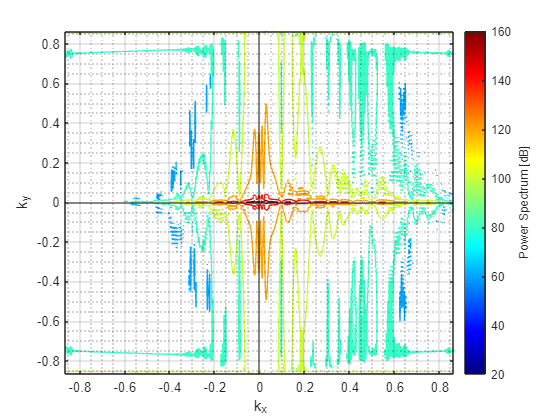

contour(k_x,k_y,EDiff_k);
% hold on;
% contour(k_x,k_y,E_k);
% contour(k_x,k_y,En);

% hold off;
%title(['Number of iterations: ',num2str(numOfIterations)]);
grid on;
xlabel('$k_{x}$','interpreter','latex'), ylabel('$k_{y}$','interpreter','latex');
% matlab2tikz(['../plots/results/contour_E_Diff1_7iterations_20Oct.tex']);

%% Plot output SAR spectra
%figure;
SARSpectrumPlot(abs(Pn),0,spectralBW,0);
%matlab2tikz(['../plots/results/bestFitSARSpectrum1_7iterations_20Oct.tex']);
%bestFitSARSpectrum1_20Oct
% hold on;
%SARSpectrumPlot(abs(P_s_pipeline),120,spectralBW,1);
%SARSpectrumPlot(abs(P_s)-abs(P_s_pipeline),120,spectralBW,1);
%SARSpectrumPlot(deltaPn,120,spectralBW,1);
%title('Minimised SAR Spectrum')

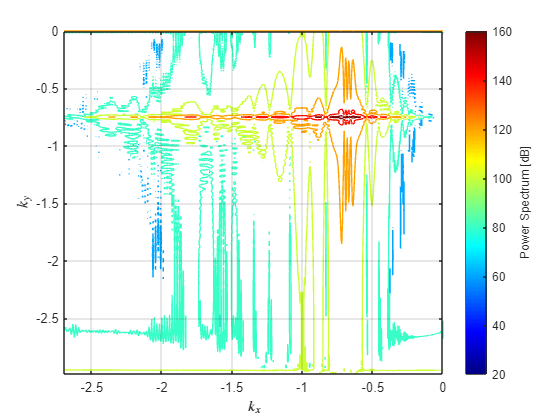

figure;
%surf(k_x,k_y,20*log10(abs(Pn)),'LineStyle','none')
contour(k_x,k_y,20*log10(abs(Pn)));

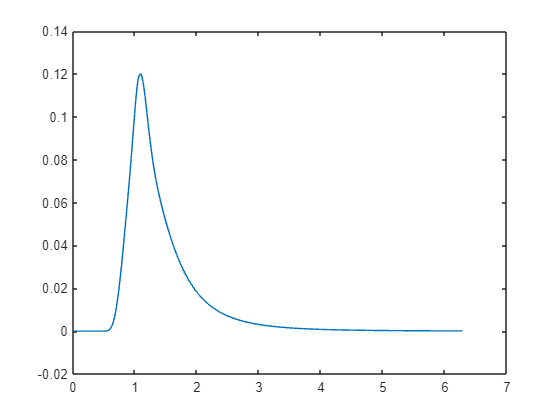

cb = colorbar;  % create and label the colorbar
cb.Label.String = 'Power Spectrum [dB]';
colormap('jet')
%title(['Best Fit SAR Spectrum for number of iterations: ',num2str(numOfIterations)]);

grid on;
yline(0);
xline(0);
xlabel('$k_{x}$','interpreter','latex'), ylabel('$k_{y}$','interpreter','latex');

%% Plot 1D spectrum
figure;
plot(w,En_w);

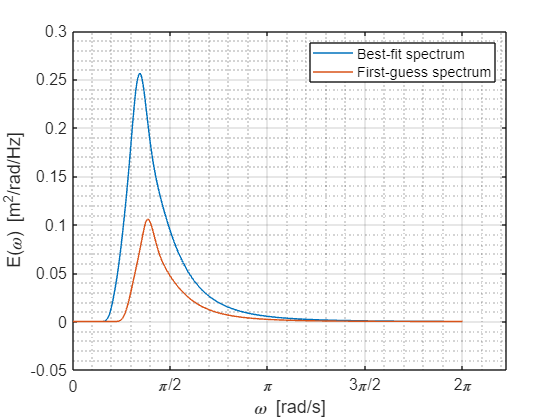

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 


 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


%% Plot 1D difference
E1DDiff = abs(En_w - S(:,:,1));
maxE1DDiff = max(E1DDiff);
maxE1DDiffIndex = find(E1DDiff == maxE1DDiff);
figure;
plot(w,En_w,'DisplayName','Best-fit spectrum');
hold on;
plot(w,S,'DisplayName','First-guess spectrum');

maxIndexS = find(S == max(S));
maxIndexEn = find(En_w == max(En_w));
%title(['One-dimensional wave spectrum, E(\omega) at ', num2str(waveVals.latitude(1,1)), 'S, ', num2str(waveVals.longitude(1,1)), 'E'])
%legend('JONSWAP for \gamma = 1.308','Location','Northeast')
xlabel('\omega [rad/s]')
ylabel('E(\omega) [m^2/rad/Hz]')
grid on;
% xline(w(maxIndexS),LineWidth=1,DisplayName=['\omega = ',num2str(round(w(maxIndexS),3))],Color="#D95319",LineStyle="--");
% xline(w(maxIndexEn),LineWidth=1,DisplayName=['\omega = ',num2str(round(w(maxIndexEn),3))],Color="#0072BD",LineStyle="--");
%plot(w,E1DDiff,'DisplayName','Difference');
hold off;
legend('show');
xlabel('\omega [rad/s]')
ylabel('E(\omega) [m^2/rad/Hz]')
%yline(maxE1DDiff,'LineStyle','--','Color','m','DisplayName',['Maximum Difference = ',num2str(maxE1DDiff)]);
grid on;
grid minor;

% set(gca,'XTick',0:0.25:1) 
% set(gca,'XTickLabel',{'0','0.25','0.5','0.75','1'})
set(gca,'XTick',0:pi/2:2*pi) 
set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})
set(gca,'FontSize',12)
%matlab2tikz(['../plots/results/oneDWaveSpec1_7iterations_20Oct.tex']);

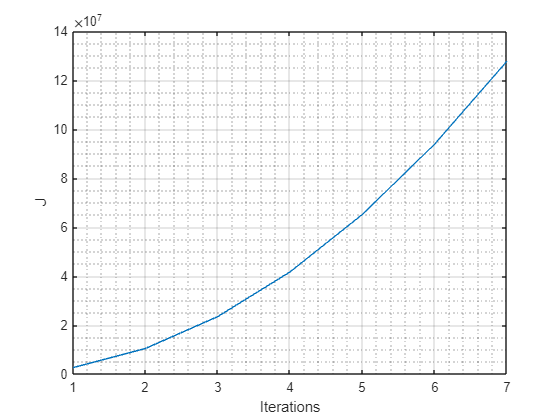

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 


 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


%% Plot J
figure;
plot(iterationVec,J)

xlabel('Iterations')
ylabel('J')
grid on;
grid minor;
% matlab2tikz(['../plots/results/J1_7iterations_20Oct.tex']);

plotMinimisedSARSpectrum = true;
if plotMinimisedSARSpectrum
    spectrumThresholdMin = 130;
    disp('Generating plot...')
    SARSpectrumPlot(20*log10(abs(Pn)),spectrumThresholdMin,spectralBW);
    title('Minimised SAR Spectrum')
    disp('Done');
end  

plotMinimised2DWaveSpectrum = true;
if plotMinimised2DWaveSpectrum
    wOrK = 1;
    contourOrSurf =1;
    if wOrK
        disp('Generating plot...');
        twoDWaveSpectrumPlot(En,wOrK,contourOrSurf,w,theta,k_x,k_y); 
        disp('Done');
    else
        disp('Generating plot...');
        twoDWaveSpectrumPlot(En,wOrK,contourOrSurf,w,theta,k_x,k_y); 
        disp('Done');
    end    
end 


plotMinimisedWaveSpectrum = true;
SMin = generateSingleJONSWAP(sigWaveHeight(end),sigWavePeriod(end),gammaVal,w);
if plotMinimisedWaveSpectrum
displaywPeak = false;
    disp('Generating plot...');
    waveSpectrumPlot(waveVals,SMin,w,multipleWaveSpectra,displaywPeak,plotLats,plotLons);
    disp('Done');   
end    

figure;
plot(iterationVec,J);



SARSpectrumPlot(20*log10(abs(Pn)),125,spectralBW);
title('Minimised SAR Spectrum');

SARSpectrumPlot(20*log10(abs(p_s_2n)),52,spectralBW);
title('P_{n,2n}^S');

SARSpectrumPlot(20*log10(abs(p_s_2n_1)),0,spectralBW);
title('P_{n,2n-1}^S');

SARSpectrumPlot(20*log10(abs(p_s_2n_2)),0,spectralBW);
title('P_{n,2n-2}^S');

### Generate SAR spectrum of Ocean Waves

Extract desired metadata

func = helperFunctions;
look = func.getLook(metadata);
% Discretise look according to HH
look = func.look(look);
polarisation = func.getPolarisation(metadata);
beta = func.getBeta(metadata);

#### Calculate co- and autocovariance functions

% Update to take in metadata vals defined above, rather than metadata
[f_v_r] = orbitalVelocityCovariance(k,k_y,E_k,metadata,r,incidenceAngle);
[f_r_r] = rarImageIntensityAutocovariance(k,k_y,E_k,metadata,r,incidenceAngle);
[f_rv_r] = rarImageIntensityCovariance(k,k_y,E_k,metadata,r,incidenceAngle);
[p_s_coeff,beta,xi_sqr] = quasilinearCoeff(k,k_y,k_x,E_k,metadata,incidenceAngle);

#### Calculate Spectral Expansions

Define the non-linearity order

defineNonLin =  true;
if defineNonLin
    nonLinOrder = 1;
else
    nonLinOrder = 1:6;
end
[p_s_2n] = spectralExpansion2n(f_v_r,nonLinOrder);
f_rv_r_inv = rarImageIntensityCovariance(k,k_y,E_k,metadata,-1.*r,incidenceAngle);
[p_s_2n_1] = spectralExpansion2n_1(f_rv_r,f_rv_r_inv,f_v_r,nonLinOrder);
f_rv_r_zero = rarImageIntensityCovariance(k,k_y,E_k,metadata,0.*r,th);
[p_s_2n_2] = spectralExpansion2n_2(f_r_r,f_v_r,f_rv_r,f_rv_r_zero,f_rv_r_inv,1);

#### Full Spectral Expansion

P_s = zeros(512,512);
func = helperFunctions;
k_x_resize = func.resize(k_x,zeros(1,2001));
k_y_resize = func.resize(k_y,zeros(1,2001));
k_resize = sqrt(k_x_resize.^2+k_y_resize.^2);
theta_resize = func.resize(theta',zeros(1,2001));
for nonLinOrder = min(nonLinOrder):max(nonLinOrder)
    for m = 2*nonLinOrder-2:2*nonLinOrder
        fprintf('m = %d, ',m)
        fprintf('n = %d \n',nonLinOrder)
        coeff = ((k_x.*beta).^m);
        if (m == 2*nonLinOrder)
            fprintf('P_(n,2n) used \n')
            P_s = P_s + coeff.*p_s_2n;
        end
        if (m == 2*nonLinOrder-1)
            fprintf('P_(n,2n-1) used \n')
            P_s = P_s + coeff.*p_s_2n_1;
        end        
        if (m == 2*nonLinOrder-2)
            fprintf('P_(n,2n-2) used\n')
            P_s = P_s + coeff.*p_s_2n_2;
        end
        
    end
end
P_s = p_s_coeff.*P_s;

Get Linear SAR spectrum

P_s_lin = imageVarianceSpectrum(k,k_x,k_y,E_k,E_k_inv,metadata,incidenceAngle);

### Inversion

## Output Parameters